# Script for computing the BER for BPSK modulation in a Rayleigh fading channel

- Single-tap channel

clear
%number of bits or symbols
No_Bits = 10^6;
% generate 0,1 with equal prob
indEX = rand(1,No_Bits)>0.5;
% BPSK modulation [0 -> -1; 1 -> 0]
s = 2*indEX-1;  
% multiple Eb/N0 values
Eb_N0_dB = [-20:40]; 

for i = 1:length(Eb_N0_dB)
   % white gaussian noise, 0dB variance 
   n = 1/sqrt(2)*[randn(1,No_Bits) + 1i*randn(1,No_Bits)]; 
   % Rayleigh channel
   h = 1/sqrt(2)*[randn(1,No_Bits) + 1i*randn(1,No_Bits)]; 
   % adding Channel and noise Noise addition
   y = h.*s + 10^(-Eb_N0_dB(i)/20)*n; 
   % the equalization
   yHat = y./h;
   % receiver with hard decision decoding
   indEXHat = real(yHat)>0;
   % counting the errors
   nErr(i) = size(find([indEX- indEXHat]),2);

end
%Calculations
Simulated_BER = nErr/No_Bits; 
theoritical_Ber_AWGN = 0.5*erfc(sqrt(10.^(Eb_N0_dB/10))); 
EbN0Lin = 10.^(Eb_N0_dB/10);
theoritical_Ber = 0.5.*(1-sqrt(EbN0Lin./(EbN0Lin+1)));


Ploting Outputs

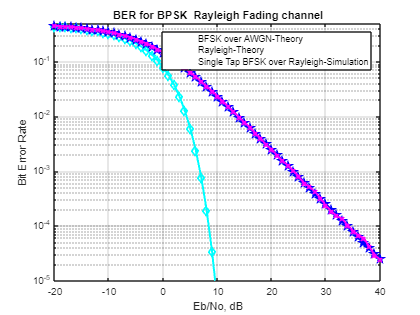

close all
figure
semilogy(Eb_N0_dB,theoritical_Ber_AWGN,'cd-','LineWidth',2);
hold on
semilogy(Eb_N0_dB,theoritical_Ber,'bp-','LineWidth',2);
semilogy(Eb_N0_dB,Simulated_BER,'mx-','LineWidth',2);
axis([-20 40 10^-5 0.5])
grid on
legend('BFSK over AWGN-Theory','Rayleigh-Theory', 'Single Tap BFSK over Rayleigh-Simulation');
xlabel('Eb/No, dB');
ylabel('Bit Error Rate');
title('BER for BPSK  Rayleigh Fading channel');

- Two-tap (with equal power) channel

K = 4;


for ii = 1:length(Eb_N0_dB)


   ip = rand(1,No_Bits)>0.5; 
   s = 2*ip-1; 

   % Channel model, multipath channel
   nTap = 2;
   ht = [0.5 0.9 0.3]; 

   chanOut = conv(s,ht);  
   n = 1/sqrt(2)*[randn(1,No_Bits+length(ht)-1) + 1i*randn(1,No_Bits+length(ht)-1)]; % white gaussian noise, 0dB variance 
   
   % Noise addition
   y = chanOut + 10^(-Eb_N0_dB(ii)/20)*n; 

   for kk = 1:K

     L  = length(ht);
     hM = toeplitz([ht([2:end]) zeros(1,2*kk+1-L+1)], [ ht([2:-1:1]) zeros(1,2*kk+1-L+1) ]);
     d  = zeros(1,2*kk+1);
     d(kk+1) = 1;
     c  = [inv(hM)*d.'].';

     % mathched filter
     yFilt = conv(y,c);
     yFilt = yFilt(kk+2:end); 
     yFilt = conv(yFilt,ones(1,1)); % convolution
     ySamp = yFilt(1:1:No_Bits);  % sampling at time T
   

     % receiver - hard decision decoding
     ipHat = real(ySamp)>0;

     % counting the errors
     nErr(kk,ii) = size(find([ip- ipHat]),2);

   end
   

end

simBer = nErr/No_Bits; % simulated ber
theoryBer = 0.5*erfc(sqrt(10.^(Eb_N0_dB/10))); % theoretical ber


Plot

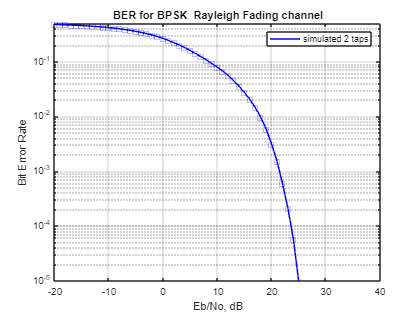

close all
figure
semilogy(Eb_N0_dB,simBer(1,:),'bs-');
hold on
axis([-20 40 10^-5 0.5])
grid on
legend('simulated 2 taps');
xlabel('Eb/No, dB');
ylabel('Bit Error Rate');
title('BER for BPSK  Rayleigh Fading channel');

- Merge Outputs

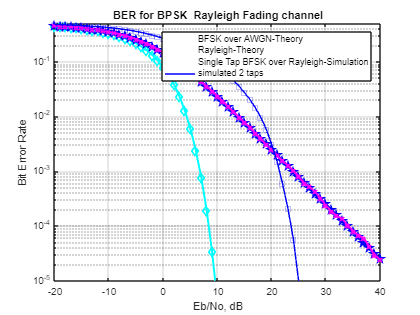

close all
figure
semilogy(Eb_N0_dB,theoritical_Ber_AWGN,'cd-','LineWidth',2);
hold on
semilogy(Eb_N0_dB,theoritical_Ber,'bp-','LineWidth',2);
semilogy(Eb_N0_dB,Simulated_BER,'mx-','LineWidth',2);
semilogy(Eb_N0_dB,simBer(1,:),'bs-');
axis([-20 40 10^-5 0.5])
grid on
legend('BFSK over AWGN-Theory','Rayleigh-Theory', 'Single Tap BFSK over Rayleigh-Simulation', 'simulated 2 taps');
xlabel('Eb/No, dB');
ylabel('Bit Error Rate');
title('BER for BPSK  Rayleigh Fading channel');